# INPUT

% [audio_data, Fs] = audioread("passwordmedium.wav");
[audio_data, Fs] = audioread("passwordhigh.wav");
% sound(audio_data, Fs, 8);

## Audio player

% sound(audio_data, Fs, 8);
dt = 1/Fs;
len_time = length(audio_data) / Fs

len_time = 2

time =linspace(0,len_time,length(audio_data));

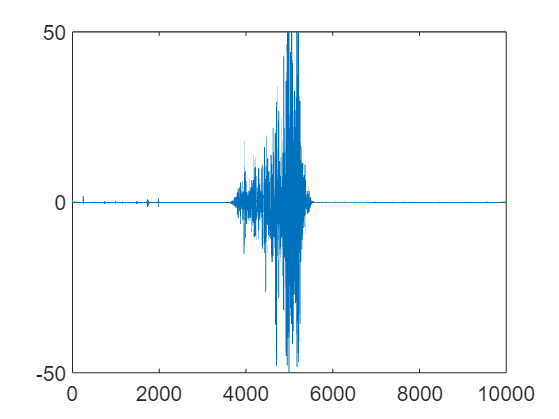

outputsignal = filter(untitled,audio_data);
x = real(fft(outputsignal));
plot(x);
xlim([0 10000])
ylim([-600 600])

% b = fir1(15,[0.3 0.6])
% freqz(b,1,512)

% nfft = 1024;
% f = linspace(0,Fs,nfft);
% Y = abs(fft(audio_data,nfft));
% figure;
% plot(f(1:nfft/2),Y(1:nfft/2))
% x = real(fft(audio_data));
% plot(x);
% 
% xlim([0 3000])
% ylim([-800 800])

## Plot for amplitude vs Time

% figure(1)
% plot(time,audio_data);
% xlabel("TIME");
% ylabel("AMPLITUDE");
% title("2notes.wav");
% hold on
% plot(time,noise_data);
% hold off

## Power and Normarlized_Power

% length(audio_data)
% new_length = length(audio_data)/2;
% audio_data_half = audio_data(1:new_length);

% function [pow] = pow(timeLeft,timeRight,amp)
%     pow=0;
%     for i = timeLeft:timeRight
%         pow = pow + amp(i)^2;
%     end
% end


function Hd = untitled
%UNTITLED 返回离散时间滤波器对象。

% MATLAB Code
% Generated by MATLAB(R) 23.2 and Signal Processing Toolbox 23.2.
% Generated on: 06-Dec-2023 15:19:10

% Equiripple Bandpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 44300;  % Sampling Frequency

Fstop1 = 1800;            % First Stopband Frequency
Fpass1 = 2000;            % First Passband Frequency
Fpass2 = 2400;            % Second Passband Frequency
Fstop2 = 2800;            % Second Stopband Frequency
Dstop1 = 0.001;           % First Stopband Attenuation
Dpass  = 0.057501127785;  % Passband Ripple
Dstop2 = 0.0001;          % Second Stopband Attenuation
dens   = 20;              % Density Factor

% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fstop1 Fpass1 Fpass2 Fstop2]/(Fs/2), [0 1 ...
                          0], [Dstop1 Dpass Dstop2]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);
end
% [EOF]

